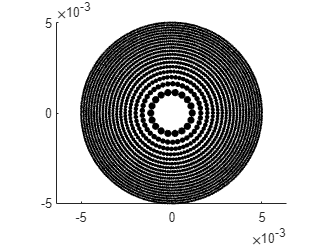

clear;
clc;
clf;
t1=clock;
%"大口径光子筛小孔环带设计方法研究_周润"
%"光子筛在空间光学应用中的关键技术研究-闫俊良"

f1=0.01;
D1=0.01;
lamda1=656.45e-9;
eta1=1.2;

% 目标为生成光子筛图样

hole=[];    %用于存放每一个产出的孔径
number=0;   %计数用

N1=N(D1,lamda1,f1);
%n1=Number(D1,lamda1,f1);这个公式算了算感觉是有一点问题的
for i=1:N1
    r_m1=r_m(i,lamda1,f1);
    w_m1=w_m(r_m1,lamda1,f1);
    N_m1=N_m(0.9,eta1,r_m1,w_m1);
    d=eta1*w_m1;
    for j=0:2*pi/N_m1:2*pi
        x=r_m1*cos(j);
        y=r_m1*sin(j);
        hole=[hole;[x y d/2]];
        number=number+1;
        rectangle('Position',[x-d/2,y-d/2,d,d],'FaceColor','k',...
        'EdgeColor','k','Curvature',[1 1])
    end
end

save sample_test hole


axis equal    

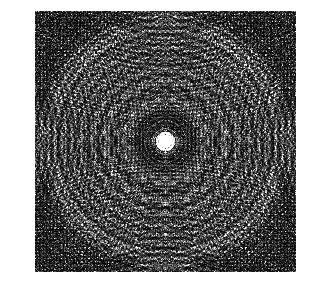


delta=5e-6;%采样间隔
A=zeros([2000,2000]);
for i=1:number
    A=addcirc(A,2*hole(i,3),hole(i,1),hole(i,2),delta);
end


B=TF_propagator(A,10,632.8e-6,1000);%单位mm

B=B.*conj(B);
imshow(B)

t2=clock;
etime(t2,t1)

ans = 39.0190

function u2=TF_propagator(u1,L,lambda,Z)
%k=2*pi/lambda; % 波数
[M,N]=size(u1); % 采样长度
dx=L/M; % 采样间隔
dy=L/N;
fx=-1/(2*dx):1/L: 1/(2*dx)-1/L; % 频率域坐标
fy=-1/(2*dy):1/L: 1/(2*dy)-1/L;
[fX,fY]=meshgrid(fx,fy); % 频率域坐标网格
H=exp(-1i*3.1415923*lambda*Z*(fX.^2+fY.^2)); % 传递函数
H=fftshift(H); % 移位操作
U1=fft2(fftshift(u1)); % 衍射孔径的移位和 FFT
U2=H.*U1; % 相乘
u2=ifftshift(ifft2(U2)); % 考察平面的光场
end

function matrixa=addcirc(A,d,x,y,delta)
%A输入平面,d为孔大小,dlta采样间隔,这是一个特化的函数
a=round(x/delta);
b=round(y/delta);
r=round(d/(2*delta));
n=0;
for i=-r:r
    for j=-r:r
        if (i)^2+(j)^2<r^2 && a+i>-1000 && a+i<1000 && b+j>-1000 && b+j<1000
            A(1000+a+i,1000+b+j)=1;
            n=n+1;
        end
    end
end
matrixa=A;
end


function r=r_m(m,lamda,f)   %算环带半径
    r=(m^2*lamda^2+2*m*lamda*f)^0.5;
end

%算环带间隔,明带,自变量明带半径
function w=w_m(R,lamda,f)
    w=lamda*f/(2*R);
end

%算孔径数,自变量口径 有点毛病
%function n=Number(D,lamda,f)
%    n=fix(0.1125*D^2/(lamda*f)^2);
%end

%算环带数
function n=N(D,lamda,f)
    n=fix(D*D/(8*f*lamda));
end

%按照指定填充因子计算m环孔径数
function N=N_m(epsilon,eta,r_m0,w_m0)
    N=fix(epsilon*2*pi*r_m0/(eta*w_m0));
end
